clear
rosshutdown

Shutting down global node /matlab_global_node_37039 with NodeURI http://192.168.87.106:50678/



OwnComputerIP = 'ROS_IP';'192.168.87.106';
OwnComputerHost = '192.168.87.106';
RobotIP = 'http://192.168.87.115:11311';

rosshutdown
setenv('ROS_MASTER_URI',RobotIP)
setenv(OwnComputerIP)
rosinit(RobotIP,'NodeHost', OwnComputerHost);

Initializing global node /matlab_global_node_09725 with NodeURI http://192.168.87.106:50752/


% Create Occupancy Map
image = imread('shannon.png');

% Convert to grayscale image
grayMap = rgb2gray(image);
bwMap = grayMap < 220;

grid = robotics.BinaryOccupancyGrid(bwMap);
map = flipud(grid.getOccupancy());

% Find shortest path
robotInitialLocation = [1112; 650]; 
robotGoal = [150; 250]; 

dx = DXform(map);
dx.plan(robotGoal);
path = dx.query(robotInitialLocation); 

%path = [0 0; 0 0.5; 0 1; 0 1.5; 0 2; 0.5 2; 1 2; 1.5 2; 2 2; 2.5 2; 3 2; 3 1.5; 3 1; 3 0.5; 3 0; 2.5 0;2 0;1.5 0;1 0; 0.5 0];
%robotInitialLocation = path(1,:);
%robotGoal = path(end,:);
robotInitialPos = [1112 650];
initialOrientation = -90;
robotCurrentPose = [robotInitialPos, initialOrientation];

robot = differentialDriveKinematics("TrackWidth", 0.5, "VehicleInputs", "VehicleSpeedHeadingRate");

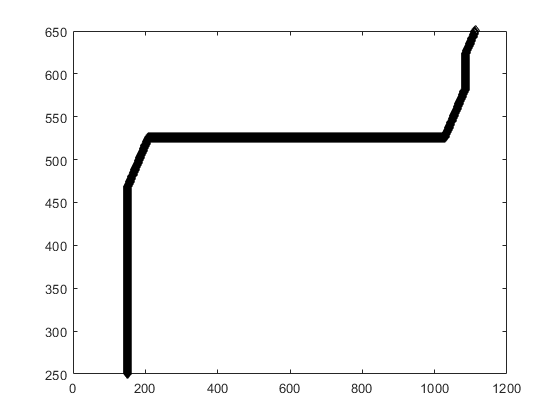

figure
plot(path(:,1), path(:,2),'k--d')

controller = controllerPurePursuit;

controller.Waypoints = path;

controller.DesiredLinearVelocity = 0.4;

controller.MaxAngularVelocity = 1;

controller.LookaheadDistance = 0.5;

goalRadius = 0.1;
distanceToGoal = norm(robotInitialPos - robotGoal);

% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
%frameSize = robot.TrackWidth/0.8;

robotRealLife = rospublisher('/mobile_base/commands/velocity');
odom = rossubscriber('/odom');

resetPos = rospublisher('/mobile_base/commands/reset_odometry');
velmsg = rosmessage(robotRealLife);
resetmsg = rosmessage(resetPos);
send(resetPos, resetmsg);

% Drive until reaching goal destination
while( distanceToGoal > goalRadius )
    % Compute the controller outputs, i.e., the inputs to the robot
    disp(robotCurrentPose)
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
 
    velmsg.Angular.Z = omega;
    velmsg.Linear.X = v;
    %velmsg.Angular.Y = vel(2);
    send(robotRealLife,velmsg);
   
    %Trying to use the robot position
    odomdata = receive(odom);
    pose = odomdata.Pose.Pose;
    quat = pose.Orientation;
    angles = quat2eul([quat.W quat.X quat.Y quat.Z]);
    robotCurrentPose = [pose.Position.X+robotInitialPos(1), pose.Position.Y+robotInitialPos(2), angles(1)];
    
    %robotCurrentPose = [x, y, z];
    
    % Update the current pose
%     temp = robotCurrentPose +vel*sampleTime
%     clear robotCurrentPose
%     robotCurrentPose = temp
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
   
   %controller.release();
    waitfor(vizRate);
end

        1112         650         -90

   1.0e+03 *

    1.1108    0.6418   -0.0015

   1.0e+03 *

    1.1108    0.6418   -0.0015

   1.0e+03 *

    1.1108    0.6417   -0.0015

   1.0e+03 *

    1.1108    0.6417   -0.0015

   1.0e+03 *

    1.1120    0.6500   -0.0000

   1.0e+03 *

    1.1120    0.6500   -0.0000

   1.0e+03 *

    1.1121    0.6500   -0.0000

   1.0e+03 *

    1.1121    0.6500   -0.0000

   1.0e+03 *

    1.1121    0.6500   -0.0000

   1.0e+03 *

    1.1121    0.6500   -0.0000

   1.0e+03 *

    1.1122    0.6500   -0.0000

   1.0e+03 *

    1.1122    0.6500   -0.0000

   1.0e+03 *

    1.1122    0.6500   -0.0000

   1.0e+03 *

    1.1122    0.6500   -0.0000

   1.0e+03 *

    1.1123    0.6500   -0.0000

   1.0e+03 *

    1.1123    0.6500   -0.0000

   1.0e+03 *

    1.1123    0.6500   -0.0000

   1.0e+03 *

    1.1123    0.6500   -0.0000

   1.0e+03 *

    1.1123    0.6500   -0.0000

   1.0e+03 *

    1.1124    0.6500   -0.0000

   1.0e+03 *

    1.1124    0.6500   -0.00


velocity = 0;
velmsg.Linear.X = velocity;
send(robotRealLife, velmsg)